# Tutorial for oFEM_v2

As oFEM has undergone some major changes, we will go over the new functionality in this short tutorial. As example we use a simple 2D capacitor.

While we use gmsh in this example, using Trelis only requires one change in the code.

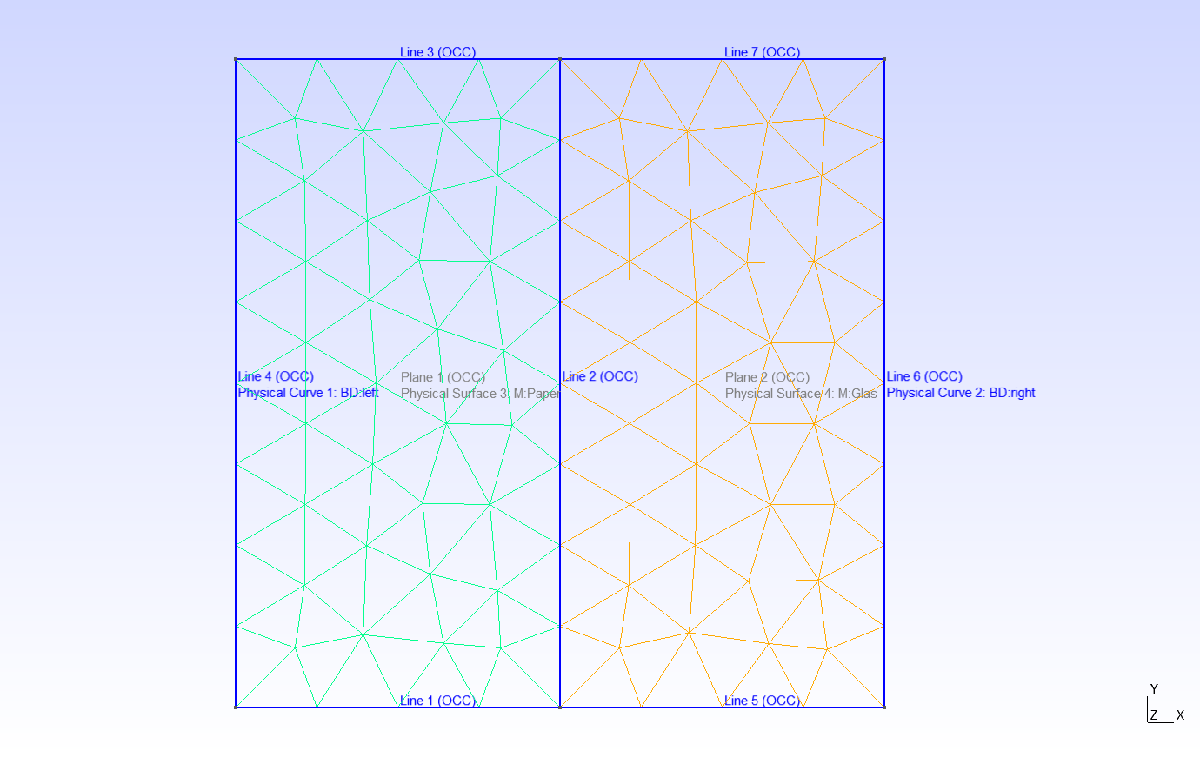

The image shows the used mesh together with the required labels. The entities labeled "Physical..." are required for the definition of the simulation. Here, "BD:" marks boundaries required for the computation and "M:" mark the different subdomains, i.e. different material regions.

## Setting up oFEM

First we need to add oFEM to the Matlab path. For this we right click the folder source in the ofem main directory and the add to path folder and subfolders. Now we can choose "Set Path" in the Matlab main window, to store the path for later sessions.

## Setting up the simulation

We start by creating an instance of the ofem geometry class, which contains all information relevant to the geometry.

mesh = ofem_v2.Geometry;            % For functions without parameters we can omit (). 
                                    % The line does still call the
                                    % generator of the class.

Next, we load the mesh, that was generated by gmsh. The file path is relative to the position of this script.

file = './geometry/CapacitorExample2D';
mesh.load_from_msh(file);           % For Trelis use load_from_inp() instead.

Error using ofem_v2.Geometry/load_from_msh (line 442)
msh-file ".\geometry\CapacitorExample2D.msh" not found.

Next we run some functions to generate extra information about the mesh. This will be hidden in another function call at a later time.

%mesh.create_faces;                 % This generates a list of all faces for 3D meshes
mesh.create_edges;                  % This generates a list of all edges in the mesh, e.g. for Boundary Conditions
%mesh.connectFa2Ed;                 % This connects the faces and edges.
                                    % This is mainly needed for the handling of degrees of freedom

Now, we need to choose our element type for the problem we want to solve. Here, we are solving a pde of the form:

                                                        
$$-\varepsilon \Delta \varphi = 0,$$


which is a laplace equation for electrostatics. Here $\varepsilon$ is the dielectric value of a material and $\varphi$ is the scalar electric potential. As this is a scalar equation with continuity in all directions, we will use H1 elements.

We have two different methods to get an instance of our elements: First, we can compute the using the symbolic toolbox, or we can simply load precomputed elements.

fe = ofem_v2.elements.H1Element(2,1);       % This creates an instance of H1 elements of dimension 2 and degree 1
fe.computeBasis;                            % This computes the actual basis

%fe = ofem_v2.elements.loadFE('H1_2D_Order_1'); % Alternatively this achieves the same, 
                                                % without spending time on the lengthy computation

All precomputed elements are stored in +ofem_v2/+elements/+preComp.

Now, we need to instantiate a DOF handler. This tells the computational routines which DOFs belong to which element and which DOFs lie on a Dirichlet boundary and so on. This is especially important for higher order elements or different operator elements.

dh = ofem_v2.DOFHandler(mesh);          % Here, we pass the mesh to the handler, 
                                        % as the handler requires the meshs information
dh.attach(fe);                          % Here we pass our element to the handler.
                                        % For different element types, the
                                        % DOFs are associated to different
                                        % geometrical entities, e.g. nodes,
                                        % edges, faces or volumes.

So far we have a mesh, an element type and a DOF handler. Now we will define the actual problem we want to solve. In this case we want to compute a capacitor:

capacitor = ofem_v2.Physical_Problem(fe, mesh, 1, 0, 0);

In the current version this call is still a little cumbersome. First we pass the element to the problem. The second argument is the mesh. The next three arguments are 0 or 1 to set the computation of the stiffness, mass and damping matrices, respectively. We still need a clearer function call for this. In this case we set the computation of the stiffness matrix only.

Now, we attach the DOF handler to the problem:

capacitor.attachDOFHandler(dh);

Our mesh has two different material regions called "Paper" and "Glas", so we will create 2 materials accordingly.

glas = ofem_v2.materials.Material;      % This creates an instance of the material class
eps_r_glas = 4.7;                       % We choose Pyrex according to wikipedia
glas.epsilon = glas.eps0 * eps_r_glas;  % eps0 is stored in the Material class as constant
glas

paper = ofem_v2.materials.Material;
eps_r_paper = 1.4;                      % eps_r for printing paper again wikipedia
paper.epsilon = paper.eps0 * eps_r_paper;
paper

Now we need to tell the mesh that we want to use those materials for the 2 regions.

mesh.setMaterial('Glas', glas);         % The region name is the same as we set in gmsh
mesh.setMaterial('Paper', paper);       % this is case sensitive!

Additionally, we need to tell the problem itself, that its stiffness matrix depends on $\varepsilon$

capacitor.setParaS('epsilon');          % To make this easier to read, 
                                        % we give the actual name of the field inside the Material instance

The same can be done for the mass and damping matrices, if the problem requires those.

Now we also need to set up the boundary conditions, to make the problem unique.

leftPotential = 1;              % First we set to values for the left and right potential in V
rightPotential = 0;

leftPlate = ofem_v2.boundary.Dirichlet(leftPotential, 'left', mesh);
rightPlate = ofem_v2.boundary.Dirichlet(rightPotential, 'right', mesh);

We do again use the names as we set them in gmsh.

Now we only need to set these boundaries up in the actual problem. This will propably be cut and automated in the above call later.

capacitor.setBoundaryCondition(leftPlate);
capacitor.setBoundaryCondition(rightPlate);

Now all information is gathered and we can generate the DOFs.

dh.generateDOFs;

Now we only need to assemble the matrices and load vectors and we can start the computation:

capacitor.assemble;
capacitor.solve;